## **Name : Thadeeya Duangkaew**

## Student ID : 6488181

## Section : 1

# **Triangulation Matting Project **

Read all 4 images

bg1 = imread('bg1.png');
bg2 = imread('bg2.png');
fg1 = imread('fg1.png');
fg2 = imread('fg2.png');

Display all 4 images

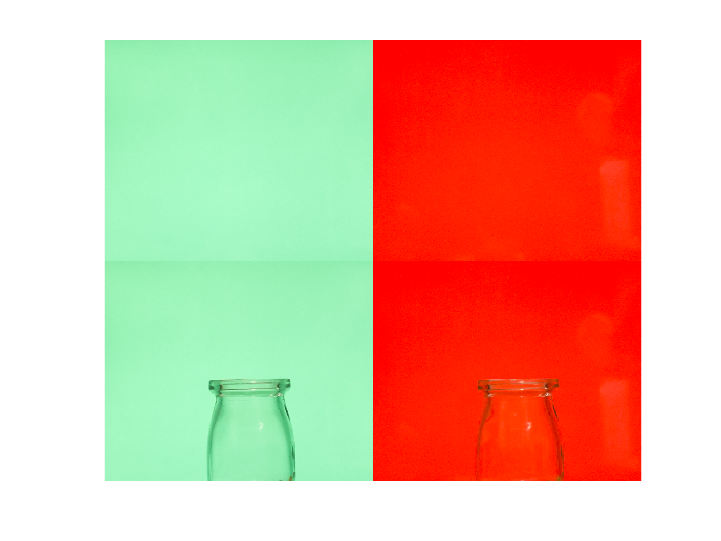

montage({bg1,bg2,fg1,fg2})

Convert to double

Dbg1 = double(imread("bg1.png")) / 255.0;
Dbg2 = double(imread("bg2.png")) / 255.0;
Dfg1 = double(imread("fg1.png")) / 255.0;
Dfg2 = double(imread("fg2.png")) / 255.0;

Compute alpha

%{
Alpha = 1 - (Numerator ./ Denominator)
Numerator = (Rfg1-Rfg2)(Rbg1-Rbg2) + (Gfg1-Gfg2)(Gbg1-Gbg2) + (Bfg1-Bfg2)(Bbg1-Bbg2)
Denominator = (Rbg1-Rbg2)^2 + (Gbg1-Gbg2)^2 + (Bbg1-Bbg2)^2
%}

Numerator = (((Dfg1(:,:,1)) - (Dfg2(:,:,1))) .* ((Dbg1(:,:,1)) - (Dbg2(:,:,1)))) + (((Dfg1(:,:,2)) - (Dfg2(:,:,2))) .* ((Dbg1(:,:,2)) - (Dbg2(:,:,2)))) + (((Dfg1(:,:,3)) - (Dfg2(:,:,3))) .* ((Dbg1(:,:,3)) - (Dbg2(:,:,3))));
Denominator = ((Dbg1(:,:,1)) - (Dbg2(:,:,1))).^2 + ((Dbg1(:,:,2)) - (Dbg2(:,:,2))).^2 + ((Dbg1(:,:,3)) - (Dbg2(:,:,3))).^2;
Alpha = 1 - (Numerator ./ Denominator)

Alpha =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

Compute foreground colors of object from background 1 

foreground1 = (Dfg1 - ((1 - Alpha) .* Dbg1)) ./ Alpha

foreground1 = foreground1(:,:,1) =

   1.0e+03 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN

Compute foreground colors of object from background 2

foreground2 = (Dfg2 - ((1 - Alpha) .* Dbg2)) ./ Alpha

foreground2 = foreground2(:,:,1) =

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    

Display the extracted foreground object / matte from background 1 and 2

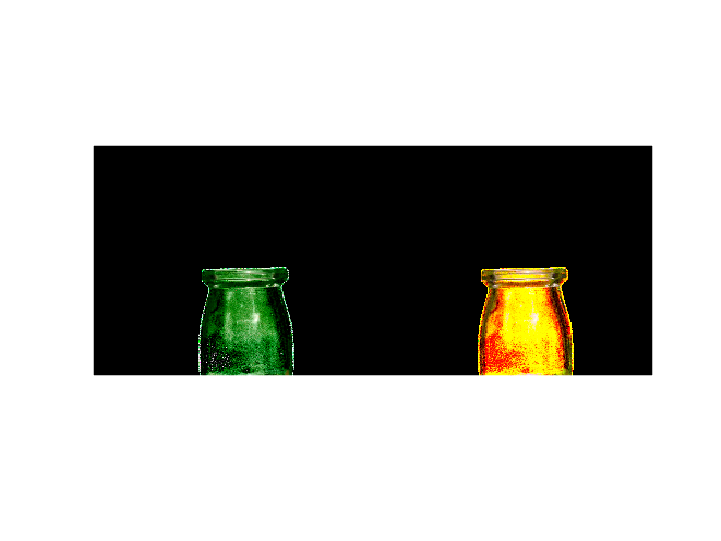

imshow([foreground1,foreground2])

Perform the composition of extracted foreground object from background 1 and 2 with the new WHITE background image

new_bg = double(imread('new_bg1.png')) / 255.0;
[row, col, colorChannel] = size(Dbg1);
WhiteImg = ones(row, col, colorChannel, 'double');

imwrite(foreground1, 'White.png');
foreground1 = im2double(imread('White.png'));
WhiteBG1 = (Alpha .* foreground1) + ((1 - Alpha) .* WhiteImg);

imwrite(foreground2, 'White.png');
foreground2 = im2double(imread('White.png'));
WhiteBG2 = (Alpha .* foreground2) + ((1 - Alpha) .* WhiteImg);

Display the composition of extracted foreground object from background 1 and 2 with the new WHITE background image

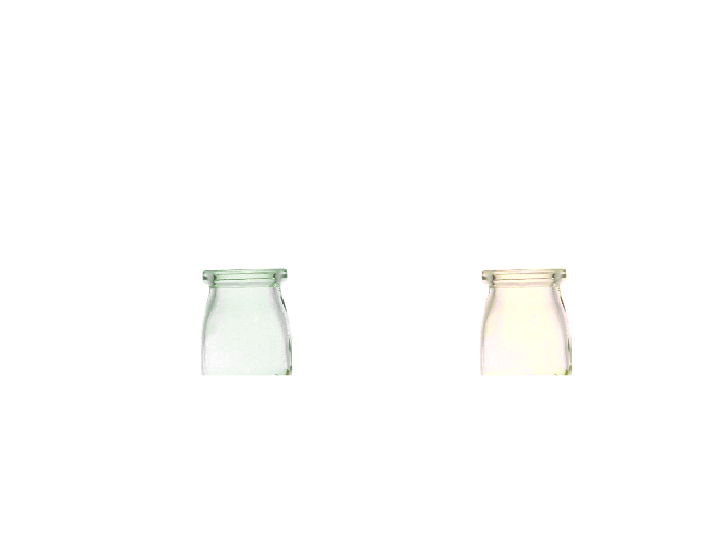

imshow([WhiteBG1,WhiteBG2])

Read new background image to do the composition and display it.

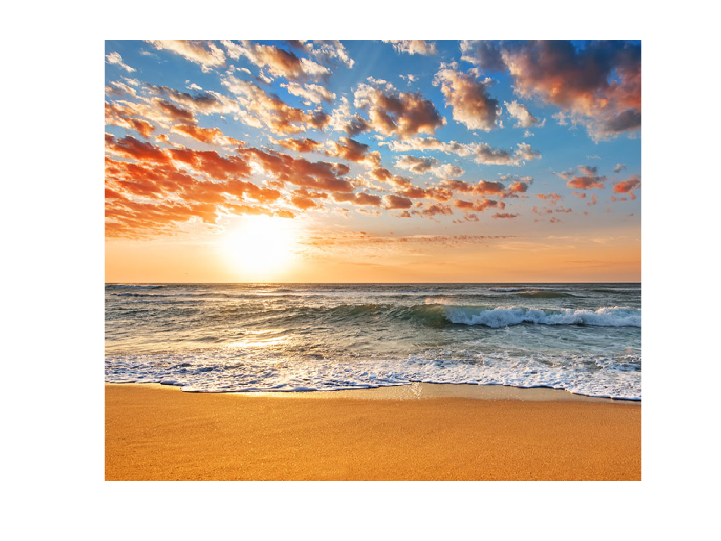

NewComposite = double(imread('new_bg1.png')) / 255.0;
imshow(NewComposite)

Perform the composition of extracted foreground object from background 1 and 2 with the new background image

imwrite(foreground1, 'NewComposite.png');
foreground1 = im2double(imread('NewComposite.png'));
NewImg1 = (Alpha .* foreground1) + ((1 - Alpha) .* NewComposite);

imwrite(foreground2, 'NewComposite.png');
foreground1 = im2double(imread('NewComposite.png'));
NewImg2 = (Alpha .* foreground2) + ((1 - Alpha) .* NewComposite);

Display the composition of extracted foreground object from background 1 and 2 with the new background image

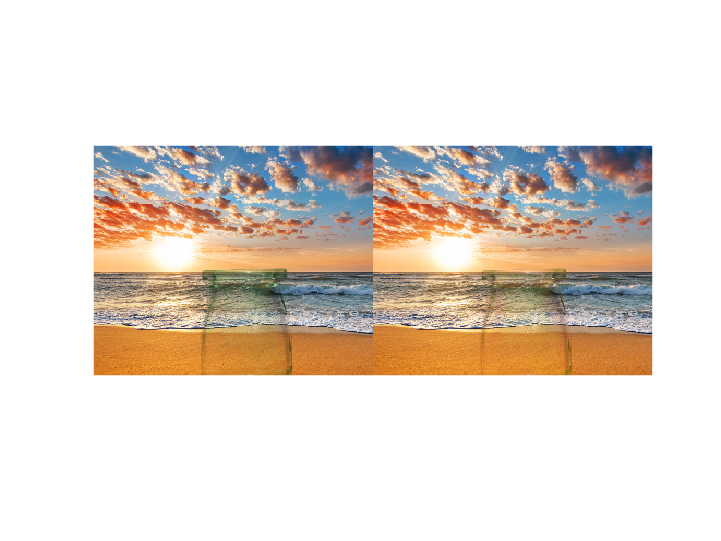

imshow([NewImg1,NewImg2])